tank1_ctd1_csv = readmatrix("data/tank1_ctd1_v2.csv");
tank1_ctd1.cond = tank1_ctd1_csv(:,2);
tank1_ctd1.sal = tank1_ctd1_csv(:,7);
tank1_ctd1.temp = tank1_ctd1_csv(:,3);
tank1_ctd1.depth = tank1_ctd1_csv(:,6);
tank1_ctd1.tank = 1;
tank1_ctd1.model = "Concerto";
tank1_ctd1.color = "r";

tank1_ctd2_csv = readmatrix("data/tank1_ctd2.csv");
tank1_ctd2.cond = tank1_ctd2_csv(:,2);
tank1_ctd2.sal = tank1_ctd2_csv(:,6);
tank1_ctd2.temp = tank1_ctd2_csv(:,3);
tank1_ctd2.depth = tank1_ctd2_csv(:,5);
tank1_ctd2.tank = 1;
tank1_ctd2.model = "xr-620";
tank1_ctd2.color = "g";

tank1_ctd3_csv = readmatrix("data/tank1_ctd3.csv");
tank1_ctd3.cond = tank1_ctd3_csv(:,2);
tank1_ctd3.sal = tank1_ctd3_csv(:,7);
tank1_ctd3.temp = tank1_ctd3_csv(:,3);
tank1_ctd3.depth = tank1_ctd3_csv(:,6);
tank1_ctd3.tank = 1;
tank1_ctd3.model = "xr-420";
tank1_ctd3.color = "b";

tank2_ctd1_csv = readmatrix("data/tank2_ctd1.csv");
tank2_ctd1.cond = tank2_ctd1_csv(:,2);
tank2_ctd1.sal = tank2_ctd1_csv(:,7);
tank2_ctd1.temp = tank2_ctd1_csv(:,3);
tank2_ctd1.depth = tank2_ctd1_csv(:,6);
tank2_ctd1.tank = 2;
tank2_ctd1.model = "Concerto";
tank2_ctd1.color = "r";

tank2_ctd2_csv = readmatrix("data/tank2_ctd2.csv");
tank2_ctd2.cond = tank2_ctd2_csv(:,2);
tank2_ctd2.sal = tank2_ctd2_csv(:,6);
tank2_ctd2.temp = tank2_ctd2_csv(:,3);
tank2_ctd2.depth = tank2_ctd2_csv(:,5);
tank2_ctd2.tank = 2;
tank2_ctd2.model = "xr-620";
tank2_ctd2.color = "g";

tank2_ctd3_csv = readmatrix("data/tank2_ctd3.csv");
tank2_ctd3.cond = tank2_ctd3_csv(:,2);
tank2_ctd3.sal = tank2_ctd3_csv(:,7);
tank2_ctd3.temp = tank2_ctd3_csv(:,3);
tank2_ctd3.depth = tank2_ctd3_csv(:,6);
tank2_ctd3.tank = 2;
tank2_ctd3.model = "xr-420";
tank2_ctd3.color = "b";

ctd_data = {tank1_ctd1, tank1_ctd2, tank1_ctd3, ...
    tank2_ctd1, tank2_ctd2, tank2_ctd3};

% Normalize depths to 0 (there's a CTD depth offset in the data)

% Cut out data from surface
cutoff = 0.1;

for i=1:length(ctd_data)
    min_val = min(ctd_data{i}.depth);
    ctd_data{i}.depth = ctd_data{i}.depth - min_val;

    % Crop data
    ctd_data{i}.mask = ctd_data{i}.depth > cutoff;
    ctd_data{i}.cond = ctd_data{i}.cond(ctd_data{i}.mask);
    ctd_data{i}.sal = ctd_data{i}.sal(ctd_data{i}.mask);
    ctd_data{i}.temp = ctd_data{i}.temp(ctd_data{i}.mask);
    ctd_data{i}.depth = ctd_data{i}.depth(ctd_data{i}.mask);

    % Separate upcast from downcast
    [val,idx] = max(ctd_data{i}.depth);
    ctd_data{i}.downMask = (1:idx);
    ctd_data{i}.upMask = (idx+1:length(ctd_data{i}.depth));

    % Compute density profile
    ctd_data{i}.rho = computeRho(ctd_data{i}.sal, ctd_data{i}.temp);
end

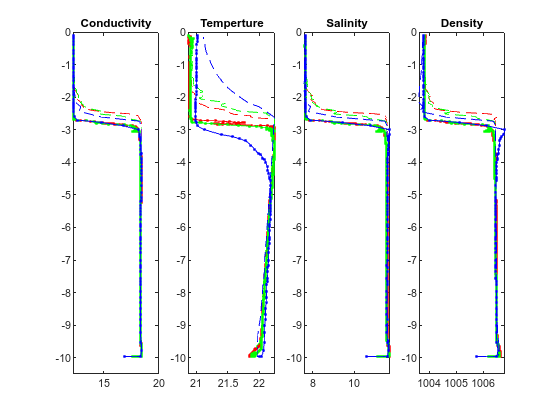

figure
subplot(1,4,1)
for i=1:length(ctd_data)
    if ctd_data{i}.tank == 2
        continue
    end

    plot(ctd_data{i}.cond(ctd_data{i}.downMask), ...
         -ctd_data{i}.depth(ctd_data{i}.downMask), ....
         ctd_data{i}.color+".-", ...
         'DisplayName', ctd_data{i}.model + " Downcast")
    hold on
    plot(ctd_data{i}.cond(ctd_data{i}.upMask), ...
         -ctd_data{i}.depth(ctd_data{i}.upMask), ....
         ctd_data{i}.color+"--", ...
         'DisplayName', ctd_data{i}.model + " Upcast")
end
title("Conductivity")
ylim([-10.5,0])

subplot(1,4,2)
for i=1:length(ctd_data)
    if ctd_data{i}.tank == 2
        continue
    end

    plot(ctd_data{i}.temp(ctd_data{i}.downMask), ...
         -ctd_data{i}.depth(ctd_data{i}.downMask), ....
         ctd_data{i}.color+".-", ...
         'DisplayName', ctd_data{i}.model + " Downcast")
    hold on
    plot(ctd_data{i}.temp(ctd_data{i}.upMask), ...
         -ctd_data{i}.depth(ctd_data{i}.upMask), ....
         ctd_data{i}.color+"--", ...
         'DisplayName', ctd_data{i}.model + " Upcast")
end
title("Temperture")
ylim([-10.5,0])

subplot(1,4,3)
for i=1:length(ctd_data)
    if ctd_data{i}.tank == 2
        continue
    end

    plot(ctd_data{i}.sal(ctd_data{i}.downMask), ...
         -ctd_data{i}.depth(ctd_data{i}.downMask), ....
         ctd_data{i}.color+".-", ...
         'DisplayName', ctd_data{i}.model + " Downcast")
    hold on
    plot(ctd_data{i}.sal(ctd_data{i}.upMask), ...
         -ctd_data{i}.depth(ctd_data{i}.upMask), ....
         ctd_data{i}.color+"--", ...
         'DisplayName', ctd_data{i}.model + " Upcast")
end
title("Salinity")
ylim([-10.5,0])

subplot(1,4,4)
for i=1:length(ctd_data)
    if ctd_data{i}.tank == 2
        continue
    end

    plot(ctd_data{i}.rho(ctd_data{i}.downMask), ...
         -ctd_data{i}.depth(ctd_data{i}.downMask), ....
         ctd_data{i}.color+".-", ...
         'DisplayName', ctd_data{i}.model + " Downcast")
    hold on
    plot(ctd_data{i}.rho(ctd_data{i}.upMask), ...
         -ctd_data{i}.depth(ctd_data{i}.upMask), ....
         ctd_data{i}.color+"--", ...
         'DisplayName', ctd_data{i}.model + " Upcast")
end
title("Density")
ylim([-10.5,0])

%legend()

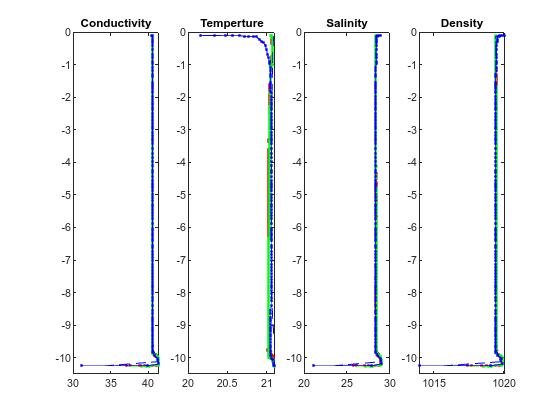

figure
subplot(1,4,1)
for i=1:length(ctd_data)
    if ctd_data{i}.tank == 1
        continue
    end

    plot(ctd_data{i}.cond(ctd_data{i}.downMask), ...
         -ctd_data{i}.depth(ctd_data{i}.downMask), ....
         ctd_data{i}.color+".-", ...
         'DisplayName', ctd_data{i}.model + " Downcast")
    hold on
    plot(ctd_data{i}.cond(ctd_data{i}.upMask), ...
         -ctd_data{i}.depth(ctd_data{i}.upMask), ....
         ctd_data{i}.color+"--", ...
         'DisplayName', ctd_data{i}.model + " Upcast")
end
title("Conductivity")
ylim([-10.5,0])

subplot(1,4,2)
for i=1:length(ctd_data)
    if ctd_data{i}.tank == 1
        continue
    end

    plot(ctd_data{i}.temp(ctd_data{i}.downMask), ...
         -ctd_data{i}.depth(ctd_data{i}.downMask), ....
         ctd_data{i}.color+".-", ...
         'DisplayName', ctd_data{i}.model + " Downcast")
    hold on
    plot(ctd_data{i}.temp(ctd_data{i}.upMask), ...
         -ctd_data{i}.depth(ctd_data{i}.upMask), ....
         ctd_data{i}.color+"--", ...
         'DisplayName', ctd_data{i}.model + " Upcast")
end
title("Temperture")
ylim([-10.5,0])

subplot(1,4,3)
for i=1:length(ctd_data)
    if ctd_data{i}.tank == 1
        continue
    end

    plot(ctd_data{i}.sal(ctd_data{i}.downMask), ...
         -ctd_data{i}.depth(ctd_data{i}.downMask), ....
         ctd_data{i}.color+".-", ...
         'DisplayName', ctd_data{i}.model + " Downcast")
    hold on
    plot(ctd_data{i}.sal(ctd_data{i}.upMask), ...
         -ctd_data{i}.depth(ctd_data{i}.upMask), ....
         ctd_data{i}.color+"--", ...
         'DisplayName', ctd_data{i}.model + " Upcast")
end
title("Salinity")
ylim([-10.5,0])

subplot(1,4,4)
for i=1:length(ctd_data)
    if ctd_data{i}.tank == 1
        continue
    end

    plot(ctd_data{i}.rho(ctd_data{i}.downMask), ...
         -ctd_data{i}.depth(ctd_data{i}.downMask), ....
         ctd_data{i}.color+".-", ...
         'DisplayName', ctd_data{i}.model + " Downcast")
    hold on
    plot(ctd_data{i}.rho(ctd_data{i}.upMask), ...
         -ctd_data{i}.depth(ctd_data{i}.upMask), ....
         ctd_data{i}.color+"--", ...
         'DisplayName', ctd_data{i}.model + " Upcast")
end
title("Density")
ylim([-10.5,0])

%legend()

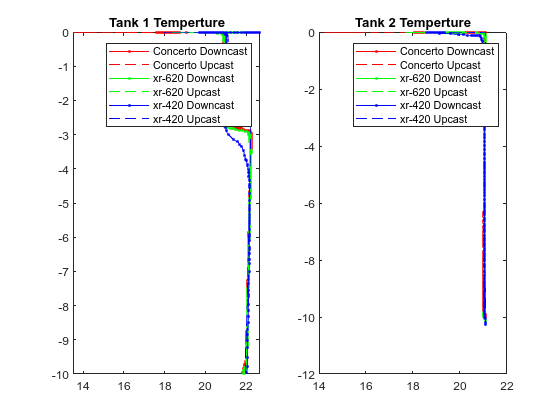

figure
subplot(1,2,1)
for i=1:length(ctd_data)
    if ctd_data{i}.tank == 2
        continue
    end
    [val,idx] = max(ctd_data{i}.depth);
    ctd_data{i}.downMask = ctd_data{i}.depth(1:idx);
    ctd_data{i}.upMask = ctd_data{i}.depth(idx+1:end);

    plot(ctd_data{i}.temp(1:idx), ...
         -ctd_data{i}.depth(1:idx), ....
         ctd_data{i}.color+".-", ...
         'DisplayName', ctd_data{i}.model + " Downcast")
    hold on
    plot(ctd_data{i}.temp(idx+1:end), ...
         -ctd_data{i}.depth(idx+1:end), ....
         ctd_data{i}.color+"--", ...
         'DisplayName', ctd_data{i}.model + " Upcast")
end
title("Tank 1 Temperture")
legend()
hold off
subplot(1,2,2)
for i=1:length(ctd_data)
    if ctd_data{i}.tank == 1
        continue
    end
    [val,idx] = max(ctd_data{i}.depth);
    ctd_data{i}.downMask = ctd_data{i}.depth(1:idx);
    ctd_data{i}.upMask = ctd_data{i}.depth(idx+1:end);

    plot(ctd_data{i}.temp(1:idx), ...
         -ctd_data{i}.depth(1:idx), ....
         ctd_data{i}.color+".-", ...
         'DisplayName', ctd_data{i}.model + " Downcast")
    hold on
    plot(ctd_data{i}.temp(idx+1:end), ...
         -ctd_data{i}.depth(idx+1:end), ....
         ctd_data{i}.color+"--", ...
         'DisplayName', ctd_data{i}.model + " Upcast")
end
title("Tank 2 Temperture")
legend()
hold off

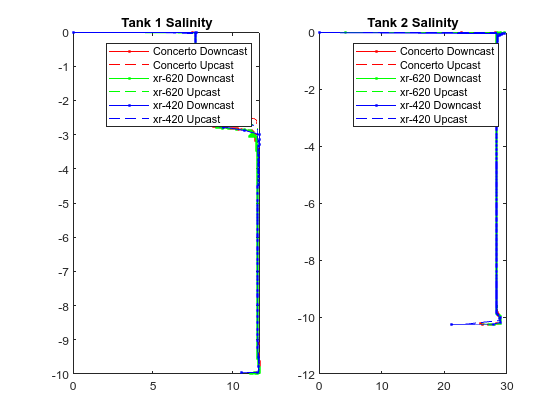

figure
subplot(1,2,1)
for i=1:length(ctd_data)
    if ctd_data{i}.tank == 2
        continue
    end
    [val,idx] = max(ctd_data{i}.depth);
    ctd_data{i}.downMask = ctd_data{i}.depth(1:idx);
    ctd_data{i}.upMask = ctd_data{i}.depth(idx+1:end);

    plot(ctd_data{i}.sal(1:idx), ...
         -ctd_data{i}.depth(1:idx), ....
         ctd_data{i}.color+".-", ...
         'DisplayName', ctd_data{i}.model + " Downcast")
    hold on
    plot(ctd_data{i}.sal(idx+1:end), ...
         -ctd_data{i}.depth(idx+1:end), ....
         ctd_data{i}.color+"--", ...
         'DisplayName', ctd_data{i}.model + " Upcast")
end
title("Tank 1 Salinity")
legend()
hold off
subplot(1,2,2)
for i=1:length(ctd_data)
    if ctd_data{i}.tank == 1
        continue
    end
    [val,idx] = max(ctd_data{i}.depth);
    ctd_data{i}.downMask = ctd_data{i}.depth(1:idx);
    ctd_data{i}.upMask = ctd_data{i}.depth(idx+1:end);

    plot(ctd_data{i}.sal(1:idx), ...
         -ctd_data{i}.depth(1:idx), ....
         ctd_data{i}.color+".-", ...
         'DisplayName', ctd_data{i}.model + " Downcast")
    hold on
    plot(ctd_data{i}.sal(idx+1:end), ...
         -ctd_data{i}.depth(idx+1:end), ....
         ctd_data{i}.color+"--", ...
         'DisplayName', ctd_data{i}.model + " Upcast")
end
title("Tank 2 Salinity")
legend()
hold off

- Flow around sensor head (salinity) - mixing on way up

- Sensor step response - less frequent sensor = more thermal inertia

- In tank 1, there's a back and forth with temperature. Doesn't show up in others

- Fresh water melt/runoff - near rivers and 

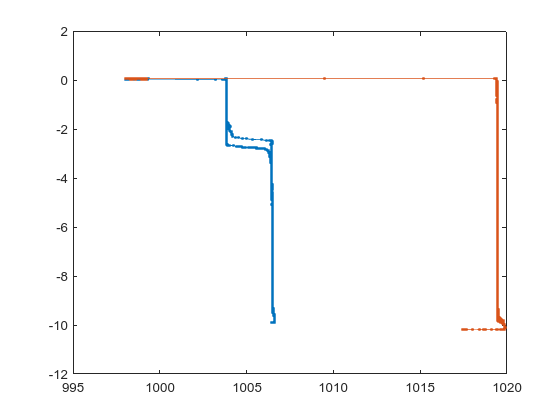

% Velocity profile

% Get max depth for reference
z_ref = -max(tank1_ctd1.depth);

% Step 1: Compute density profile
figure
tank1_ctd1.rho = computeRho(tank1_ctd1.sal, tank1_ctd1.temp);
plot(tank1_ctd1.rho, -tank1_ctd1.depth,'.-')
hold on

tank2_ctd1.rho = computeRho(tank2_ctd1.sal, tank2_ctd1.temp);
plot(tank2_ctd1.rho, -tank2_ctd1.depth,'.-')
hold off

% Isolate down profile

ctd1_tab = 1398×2 table
     depth      rho  
    _______    ______

    -9.9162    1006.5
    -9.9162    1006.4
     -9.916    1006.4
    -9.9156    1006.4
    -9.9156    1006.4
    -9.9155    1006.4
    -9.9151    1006.5
    -9.9151    1006.5
     -9.915    1006.5
     -9.915    1006.4
    -9.9149    1006.5
    -9.9143    1006.4
    -9.9138    1006.4
    -9.9133    1006.5
    -9.9132    1006.4
    -9.9125    1006.5


mask1 = 3000:4400;
ctd1_tab = table(-tank1_ctd1.depth(mask1), tank1_ctd1.rho(mask1), 'VariableNames', ["depth","rho"]);
ctd1_tab = unique(ctd1_tab)

ctd2_tab = 1695×2 table
     depth      rho  
    _______    ______

    -9.5948    1019.5
    -9.5932    1019.5
    -9.5898    1019.5
    -9.5866    1019.5
    -9.5831    1019.5
    -9.5803    1019.5
     -9.576    1019.5
    -9.5715    1019.5
    -9.5651    1019.5
     -9.558    1019.5
    -9.5516    1019.5
    -9.5418    1019.5
    -9.5332    1019.5
    -9.5239    1019.5
    -9.5151    1019.5
    -9.5053    1019.5


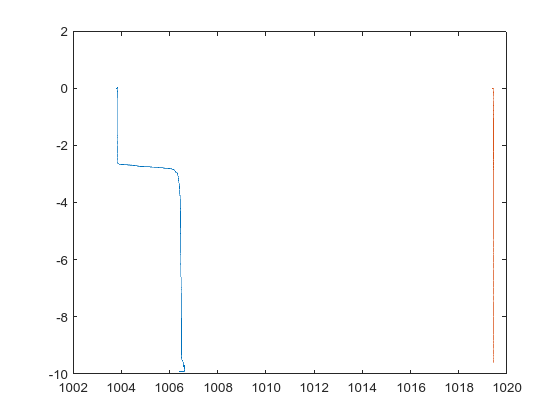

mask2 = 1300:3000;
ctd2_tab = table(-tank2_ctd1.depth(mask2), tank2_ctd1.rho(mask2), 'VariableNames', ["depth","rho"]);
ctd2_tab = unique(ctd2_tab)
plot(ctd1_tab.rho,ctd1_tab.depth)

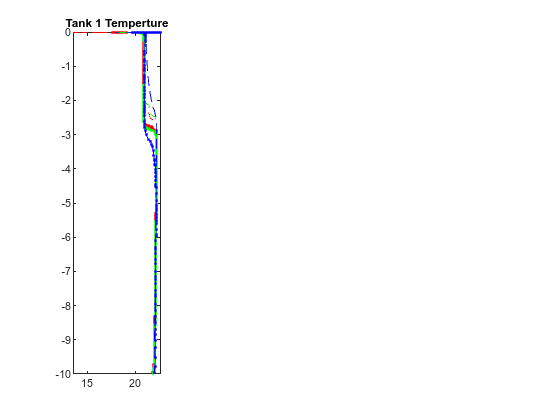

hold on
plot(ctd2_tab.rho,ctd2_tab.depth)

hold off

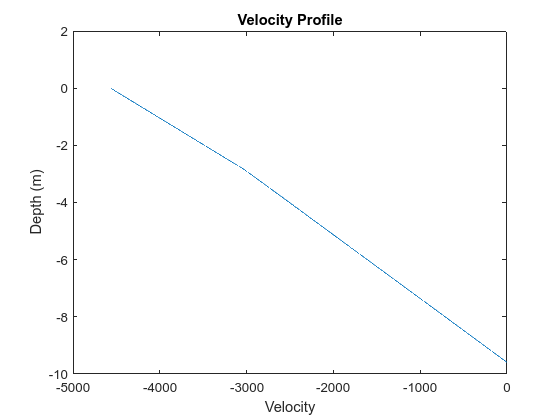


dz = diff(ctd2_tab.depth);

% Compute tank 1 density at each depth
rho1_interp = interp1(ctd1_tab.depth, ctd1_tab.rho, ctd2_tab.depth);

% Compute difference at each depth
d_rho = ctd2_tab.rho - rho1_interp;

% Integral
d_y = 3; % in meters
g = 9.8;
rho_0 = rho1_interp; % Use rho1 as reference density
omega = 7.29*(10^-5);
f = 2*omega*sin(0.7); %~ 40 degrees

plot(-g./(rho_0(2:end).*f).*cumsum(d_rho(2:end)./d_y.*dz), ctd2_tab.depth(2:end))

xlabel("Velocity")
ylabel("Depth (m)")
title("Velocity Profile")
% This result makes sense - water should flow from tank 1 to tank 2.
% Tank 1 would be higher since it flows from the less dense tank to the

ans = 0.1000

% more dense tank

computeRho(30.1231,-1.8)-computeRho(30,-1.8)

function rho = computeRho(S, T)
    rho_0 = 999.84259 ...
        + 6.793952*10^-2*(T) ...
        - 9.095290*10^-3*(T.^2) ...
        + 1.001685*10^-4*(T.^3) ...
        - 1.120083*10^-6*(T.^4) ...
        + 6.536332*10^-9*(T.^5);

    A_sp = 0.824493 ...
        - 4.0899*10^-3*(T) ...
        + 7.6438*10^-5*(T.^2) ...
        - 8.2467*10^-7*(T.^3) ...
        + 5.3875*10^-9*(T.^4);

    B_sp = -5.72466.*(10^-3) ...
        + 1.0227*(10^-4)*(T) ...
        - 1.6546*(10^-6)*(T.^2);

    C_sp = 4.8314*(10^-4);

    rho = rho_0 + A_sp.*S + B_sp.*(S.^1.5) + C_sp.*(S.^2);
end